format long g
addpath("C:\Users\Adisa\Desktop\obrada_slike_projekat\source\helpers");

Na početku se učitava video koji ima .y4m ekstenziju, često korištenju kod poređenja efikasnosti kompresije, pošto sam format ne aplicira nikakvu kompresiju nad videom. Također, prikazana je početna veličina videa u MB.

[mov, videoInfo] = yuv4mpeg2mov('C:\Users\Adisa\Desktop\obrada_slike_projekat\source\video\crew_4cif.y4m');
sizeMB(mov, 8)

ans =                  696.09375


Prvi vid kompresije koji će biti urađen jeste takozvana kvantizacija videa, frame po frame. Ideja je da se smanji opseg dozvoljenih vrijednosti za predstavljanje intenziteta piksela (kako se tačno ovo postiže je opisano u pomoćnoj funkciji "quantize"). 

Primjenom ove metode može doći do nastajanja određenih anomalija na videu, u smislu da se uslijed manjeg opsega intenziteta piksela pojavljuju određene konture koje nisu prije bile prisutne. Iako je ovaj metod prilično jednostavan za implementirati, on smanji veličinu videa za 50%, a degradacija slike nije toliko vidljiva ukoliko se ne zagleda. Ovo je primjer kompresije sa gubitkom.

quantizedMov = mov;
for i = 1:length(mov)
    quantizedMov(i).cdata = quantize(mov(i).cdata, 4);
end

Ispod je dat rezultat ove kompresije:

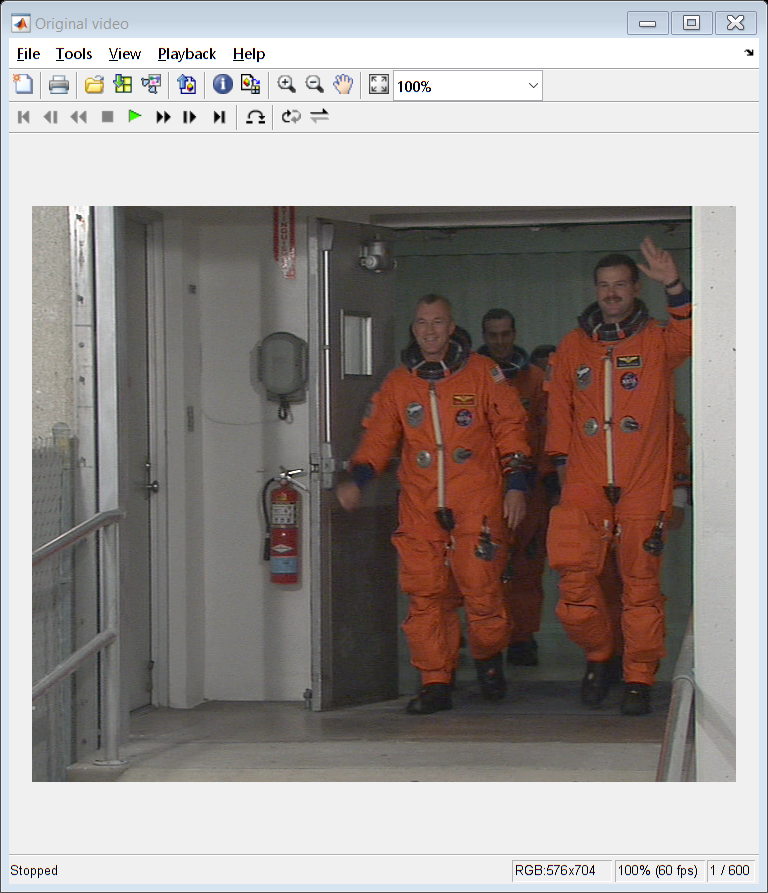

qm = implay(quantizedMov, videoInfo.fps);
m = implay(mov, videoInfo.fps);
set(qm.Parent, "Name", "Quantized video");
set(m.Parent, "Name", "Original video");
m.Parent.Position = [100 50 600 600];

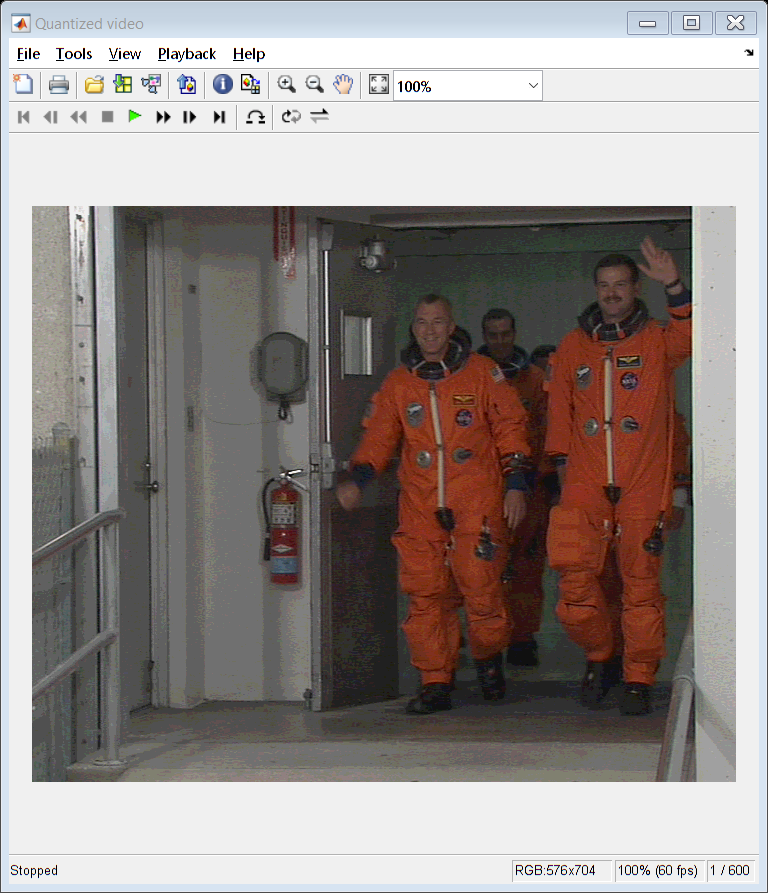

qm.Parent.Position = [700 50 600 600];

Veličina videa nakon kompresije je (u MB):

sizeMB(quantizedMov, 4)

ans =                 348.046875


Sljedeći način kompresije koji će biti urađen spada u sekciju načina kompresije koji smanjuju kodnu redundantnost videa. Ovdje će biti korišten Huffmanov kod, koji enkodira intenzitete piksela svakog frame-a pomoću optimalnog koda varijabilne dužine.

huffmanMov = cell(1, length(quantizedMov));
avgLenAll = 0;
totalBits = 0;
for i = 1:length(quantizedMov)
    img = quantizedMov(i).cdata;
    symbols = unique(img(:));
    counts = histc(img(:), symbols);
    p = counts / sum(counts);
    
    [huffDict, avgLen] = huffmandict(symbols, p);
    avgLenAll = avgLenAll + avgLen;
    encoding = huffmanenco(img(:), huffDict);
    huffmanMov{1, i} = encoding(:);
    totalBits = totalBits + length(encoding(:));
end
avgLenAll = avgLenAll / length(quantizedMov);

Svaki frame je enkodiran kao niz 0 i 1, koji se može na jedinstven način dekodirati (pošto je Huffmanov kod prefix-free kod). Na primjer, moguće je dekodirati jedan frame iz niza kodiranih frameova i dobiti originalnu sliku, bez gubitka ikakvih informacija na sljedeći način:

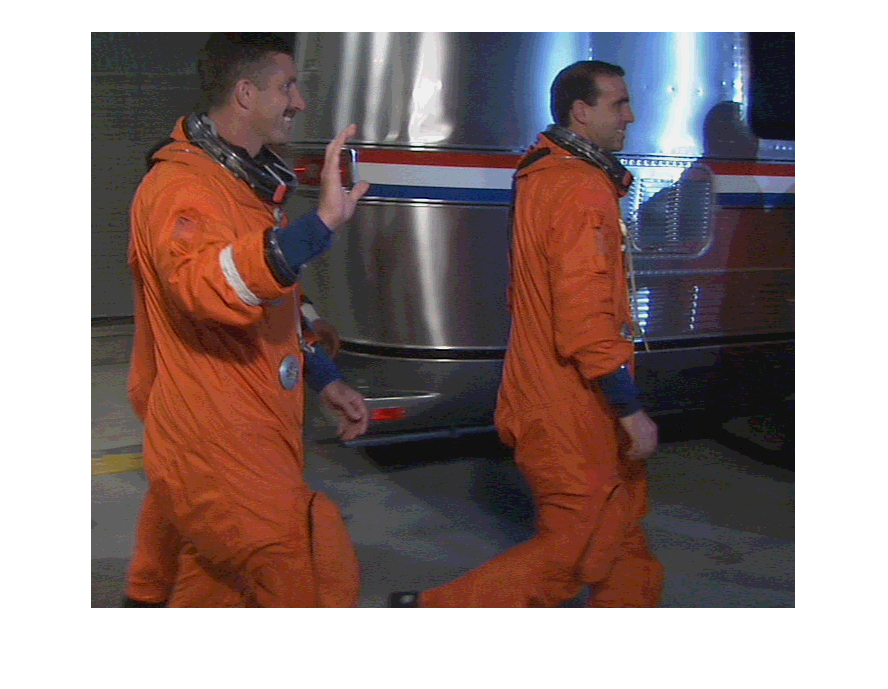

sampleDecoded = huffmandeco(huffmanMov{1, length(huffmanMov)}, huffDict);
sampleDecoded = reshape(sampleDecoded, videoInfo.height, videoInfo.width, 3);
imshow(sampleDecoded)

Prosječna dužina kodne riječi u svim Huffmanovim kodovima za sve frameove je:

avgLenAll

avgLenAll =           3.35949777040149


Pomoću Huffmanovog kodiranja video je sada veličine (u MB):

huffCodeSizeMB(huffmanMov)

ans =           292.315675139427


Dosadašnji načini kompresije koji su primijenjeni nisu koristili nikakvu zavisnost između uzastopnih frameova u videu. Upravo to će biti iskorišteno u narednom načinu kompresije koji ima za cilj uklanjanje vremenske redundantnosti u videu.

Način na koji ovaj vid kompresije radi jeste da se vrši predikcija intenziteta piksela (t, x, y), pri čemu je t redni broj frame-a, a x i y su koordinate piksela u datom frame-u. Predikcija se može izvršiti pomoću određenog broja prethodnih frame-ova, uz pretpostavku da se intenzitet piksela ne mijenja puno u susjednim frame-ovima.

Npr. funkcija predikcije ovdje korištena je: (ovdje je f(t,x,y) prava vrijednost piksela, a f' je predikcija)

f'(t, x, y) = round(alpha * (f(t-1, x, y) + f(t-2, x, y))),

pri čemu postavljamo konstantu alpha = 0.5. Dakle, piksel u frame-u t je aritmetička sredina piksela u istoj poziciji na prethodna dva frame-a. 

Nakon izračunavanja predikcija, pomoću Huffmanovog koda enkodiramo niz grešaka:

e(t, x, y) = f'(t, x, y) - f(t, x, y),

a rekonstrukciju originalne slike vršimo pomoću transformacije:

f(t, x, y) = f'(t, x, y) - e(t, x, y).

[temporalMov, decTemporalMov, avgLenHuff, predictions, errors] = temporalEncoding(quantizedMov);

Sada je prosječna dužina kodne riječi u Huffmanovim kodovima:

avgLenHuff

avgLenHuff =           2.88131883340786


Ovaj vid kompresije je bez gubitaka kao što se može i vidjeti na dekodiranom videu:

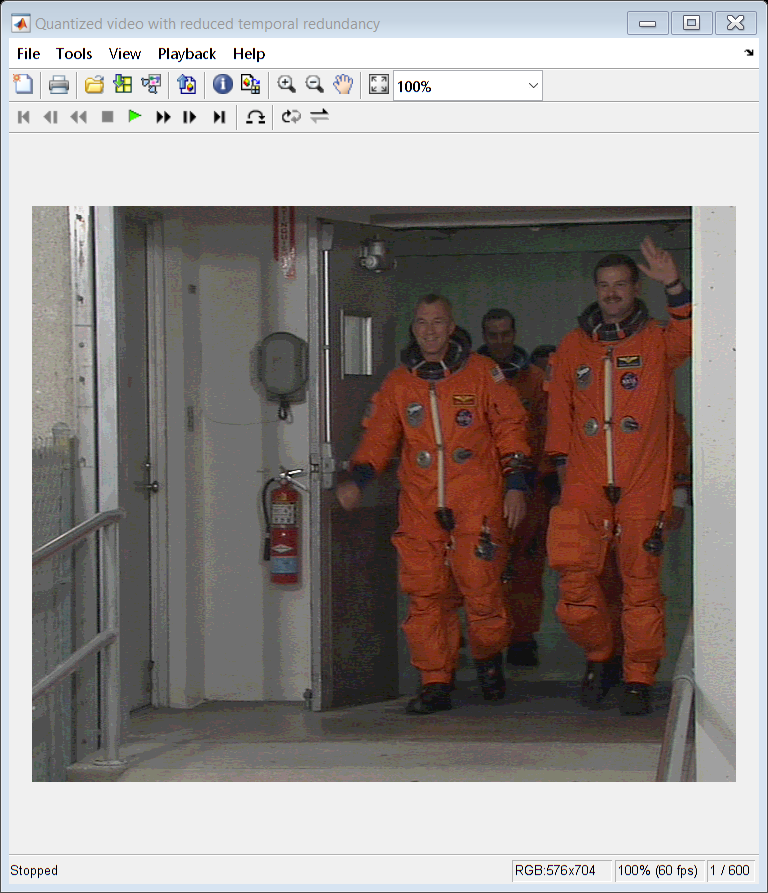

tm = implay(decTemporalMov, videoInfo.fps);
set(tm.Parent, "Name", "Quantized video with reduced temporal redundancy");
tm.Parent.Position = [300 50 600 600];

Konačno nakon i ove kompresije veličina videa u MB iznosi:

huffCodeSizeMB(temporalMov)

ans =           250.708503961563


Na kraju je veličina videa smanjena sa ~700MB na ~250MB, bez prevelikog gubitka kvalitete (samo jedan način kompresije je doprinio gubitku kvalitete).

Reference:

- Funkcija za učitavanje videa u .y4m formatu: [yuv4 reader](https://www.mathworks.com/matlabcentral/fileexchange/50690-yuv4mpeg-reader)

- Matlab dokumentacija: [MathWorks](https://www.mathworks.com/help/matlab/)

- Videi u .y4m formatu: [derf's collection](https://media.xiph.org/video/derf/)

- Knjiga "Digital image processing using MATLAB 2nd edition", Rafael C. Gonzalez et al.: [Image processing book](https://www.mathworks.com/academia/books/digital-image-processing-using-matlab-gonzalez-asia.html)